%24/02/2024 Open unform for initial side of b-spline ->NB b-spline is from
%RIGHT to LEFT
P1 = [1000, 75];
P2 = [75, 150];
P3 = [150, 10];
t1 = 0.01;
t2 = 0.02;
t3 = 0.03;
t4 = 30;
t5 = 59.98;
t6 = 59.99;
t7 = 60;
validtmin = t3;
validtmax = t4;
tmin = 0;
tmax = 60;
step = 0.01;
stackx = [];
stacky = [];
for t = tmin:step:tmax
    if (t1<=t)
        if (t<t2)
            N1k1 = 1;
        else
            N1k1 = 0;
        end
    else
        N1k1 = 0;
    end
    if (t2<=t)
        if (t<t3)
            N2k1 = 1;
        else
            N2k1 = 0;
        end
    else
        N2k1 = 0;
    end
    if (t3<=t)
        if (t<t4)
            N3k1 = 1;
        else
            N3k1= 0;
        end
    else
        N3k1 = 0;
    end
    if (t4<=t)
        if (t<t5)
            N4k1 = 1;
        else
            N4k1 = 0;
        end
    else
        N4k1 = 0;
    end
    if (t5<=t)
        if (t<t6)
            N5k1 = 1;
        else
            N5k1 = 0;
        end
    else
        N5k1 = 0;
    end
    if (t6<=t)
        if (t<t7)
            N6k1 = 1;
        else
            N6k1 = 0;
        end
    else
        N6k1 = 0;
    end

    N1k2 = ((t-t1)/(t2-t1))*N1k1 + ((t3-t)/(t3-t2))*N2k1;
    N2k2 = ((t-t2)/(t3-t2))*N2k1 + ((t4-t)/(t4-t3))*N3k1;
    N3k2 = ((t-t3)/(t4-t3))*N3k1 + ((t5-t)/(t5-t4))*N4k1;
    N4k2 = ((t-t4)/(t5-t4))*N4k1 + ((t6-t)/(t6-t5))*N5k1;
    N5k2 = ((t-t5)/(t6-t5))*N5k1 + ((t7-t)/(t7-t6))*N6k1;

    N1k3 = ((t-t1)/(t3-t1))*N1k2 + ((t4-t)/(t4-t2))*N2k2;
    N2k3 = ((t-t2)/(t4-t2))*N2k2 + ((t5-t)/(t5-t3))*N3k2;
    N3k3 = ((t-t3)/(t5-t3))*N3k2 + ((t6-t)/(t6-t4))*N4k2;
    N4k3 = ((t-t4)/(t6-t4))*N4k2 + ((t7-t)/(t7-t5))*N5k2;

    SumNPx = N1k3*P1(1,1) + N2k3*P2(1,1) + N3k3*P3(1,1);
    SumNPy = N1k3*P1(1,2) + N2k3*P2(1,2) + N3k3*P3(1,2);

    if t >= validtmin
        if t<=validtmax
            stackx = [stackx; SumNPx];
            stacky = [stacky; SumNPy];
        end
    end
end
CP = [P1; P2; P3]

CP =         1000          75
          75         150
         150          10


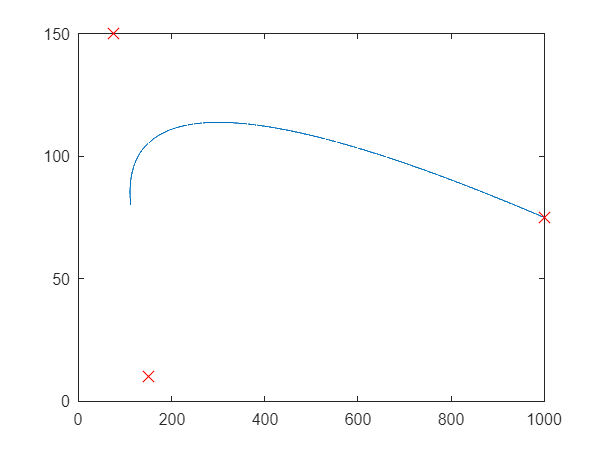

CPx = [P1(1,1), P2(1,1), P3(1,1)];
CPy = [P1(1,2), P2(1,2), P3(1,2)];
plot(stackx, stacky)
hold on
scatter(CPx, CPy, 100, "red", "X")
hold off

knotV = [t1, t2, t3, t4, t5, t6, t7]

knotV =     0.0100    0.0200    0.0300   30.0000   59.9800   59.9900   60.0000
